# **PESTools - Example 013 - ARPES Eb(kx) Data Fitting**

## Author : PCC

This example shows how to perform common operations on ARPES data using the functions of the MATools and PESTools toolkit. This example loads in ARPES data, processes it and then determines the best fit to the conduction band states that emerge near the Fermi-edge.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

close all; clear all;
pp          = plot_props();
data_path   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ADRESSTools\ADRESSTools_vEos\PESTools_PCC\Examples\Example_Data\';
save_path   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ADRESSTools\ADRESSTools_vEos\PESTools_PCC\Examples\Example_Data\';

# **(1) SX-ARPES Eb(kx) Data Processing**

help load_adress_data;

  dataStr = load_adress_data(FileName, PathName)
    This function loads in the HDF5 data files of ARPES data from 
    the ADRESS beamline at the SLS. The output is a MATLAB
    data-structure that yields all the data and information. This function 
    should be used to load in a single ADRESS data-file that is unprocessed
    or has been previously processed using PESTools. Last updated in
    October 2022, and includes electrostatic tilt extraction.
 
    REQ. FUNCTIONS:
    -   [data, axes, note]  = ReaderHDF5(fname);
    -   [DataXC,OffsE]      = SumScanXC(Energy,Data,maxLagE[,WinE]);
 
    IN:
    -   FileName:           char of the input .h5 or .mat file-name.
    -   PathName:           char of the input .h5 or .mat directory path.
    -   Reset:              if equal to 1, then reset all previous processing upon loading, otherwise leave alone.
 
    OUT:
    dataStr - MATLAB data structure containing all fields below;
 	 .(FileName):        string of the curr

**(A) Loading in the ARPES data files**

% Loading in the data files
file_names      = {...
    '010_ARPES_HSCUT.h5',...
    };
arpes_dat = cell(1,length(file_names));
for i = 1:length(file_names); arpes_dat{i} = load_adress_data(file_names{i}, data_path); end

Loading ADRESS data...


- Data slice formation
- Re-mapping


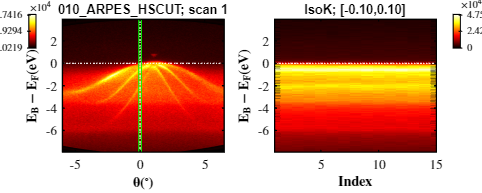

view_arpes_data(arpes_dat{1});

% Cross-correlating the data files
for i = 1:length(arpes_dat); arpes_dat{i} = xcorr_scans(arpes_dat{i}); end

- Correlating scans
Scan = 2: Offset = 0.01728
Scan = 3: Offset = 0.01728
Scan = 4: Offset = 0.01728
Scan = 5: Offset = 0.02592
Scan = 6: Offset = 0.02592
Scan = 7: Offset = 0.02592
Scan = 8: Offset = 0.02592
Scan = 9: Offset = 0.02592
Scan = 10: Offset = 0.02592
Scan = 11: Offset = 0.03456
Scan = 12: Offset = 0.03456
Scan = 13: Offset = 0.03456
Scan = 14: Offset = 0.03456
Scan = 15: Offset = 0.03456


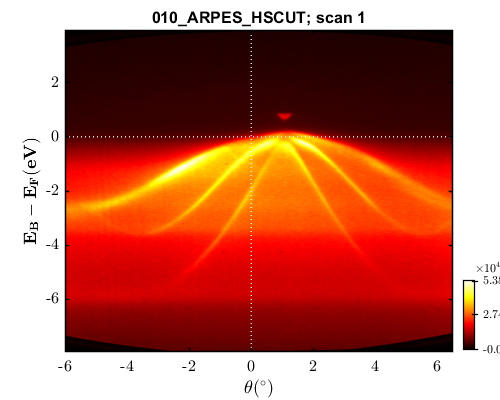

view_arpes_data(arpes_dat{1});

**(B) Loading in the Fermi-Edge reference files**

% Loading in the data files
file_names_ef      = {...
    '010_ARPES_HSCUT_EF.h5',...
    };
arpes_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); arpes_ref{i} = load_adress_data(file_names_ef{i}, data_path); end

Loading ADRESS data...


- Data slice formation
- Re-mapping


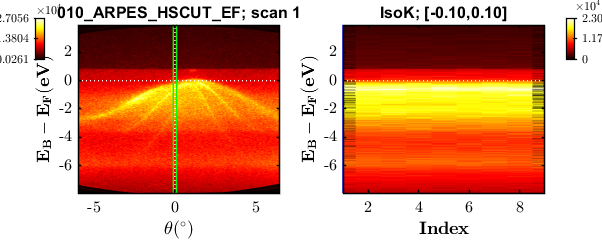

view_arpes_data(arpes_ref{1});

% Cross-correlating the reference files to get a good estimate on EF
for i = 1:length(arpes_ref); arpes_ref{i} = xcorr_scans(arpes_ref{i}); end

- Correlating scans
Scan = 2: Offset = 0
Scan = 3: Offset = 0
Scan = 4: Offset = 0
Scan = 5: Offset = 0
Scan = 6: Offset = 0
Scan = 7: Offset = 0
Scan = 8: Offset = 0
Scan = 9: Offset = 0


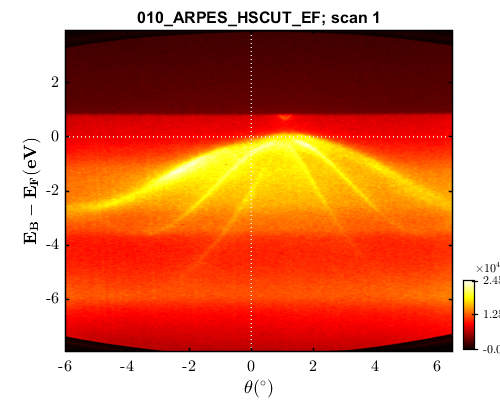

view_arpes_data(arpes_ref{1});

**(C) Binding energy alignment to the reference data**

help align_energy;

  [dataStr, dataStr_ref] = align_energy(dataStr, align_args, dataStr_ref, plot_result)
    - #1 - FIRST STEP IN PROCESSING ARPES DATA
    This is a function that will align the 'dataStr' ARPES data-structure 
    to the Fermi-level, a peak, or reference VB or CB state. The energy
    alignment is done using various approaches that the user can select from,
    either using the 'dataStr' or a reference 'dataStr_ref' data file. (1) 
    The 'align2ref' argument aligns to some peak or edge reference, (2)
    'fit2ef' fits directly to the FDD edge of a reference, (3) 'fit2peak'
    fits directly to some peak feature.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   [EAlign, EF, Fail] = AlignEF(Data, ECorr [,eWin] [,dEWin] [,dESmooth] [,feat]);
 
    IN:
    -   dataStr:            data structure of the ARPES data.
    -   align_args:         {1×6} cell of {Type,Scans,eWin, dEWin, dESmooth, feat}.
                          

- EF alignment


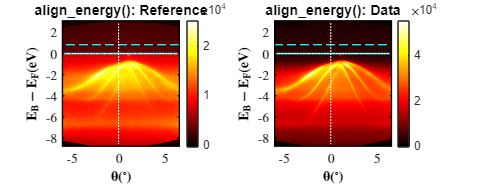

% (1) COARSE ALIGNMENT TO THE EDGE
% -- Coarse alignment of the energy
alignType   = "align2ref";
scan_indxs	= [];
eWin        = -1.0;
dEWin       = 4.00;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(arpes_dat)
    if i ==1;   [arpes_dat{i}, arpes_ref{i}] = align_energy(arpes_dat{i}, align_args, arpes_ref{i}, 1);
    else;       [arpes_dat{i}, arpes_ref{i}] = align_energy(arpes_dat{i}, align_args, arpes_ref{i});
    end
end

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


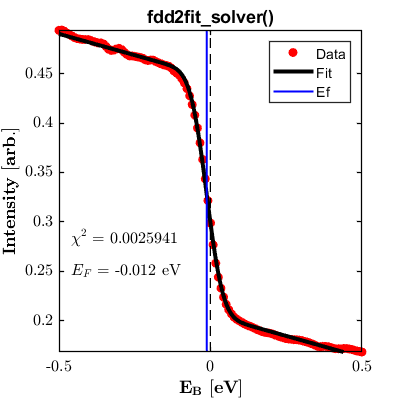

Ef = -0.0121

% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef";
scan_indxs	= [];
eWin        = 0.00;
dEWin       = 0.50;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(arpes_dat)
    if i ==1;   arpes_dat{i} = align_energy(arpes_dat{i}, align_args, arpes_ref{i}, 1);
    else;       arpes_dat{i} = align_energy(arpes_dat{i}, align_args, arpes_ref{i});
    end
end

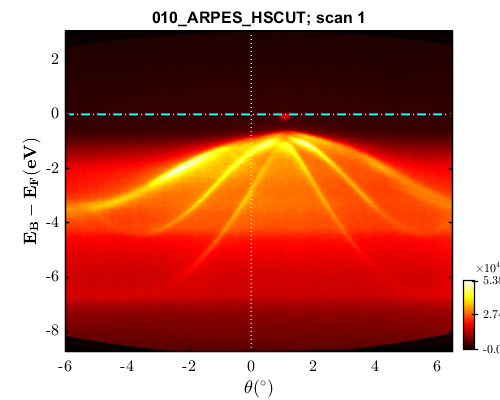

% (3) PLOT OF THE FINAL RESULT
view_arpes_data(arpes_dat{1}); line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--');

**(D) Background subtraction and intensity normalisation**

help bgrd_subtr_data;

  dataStr = bgrd_subtr_data(dataStr, bsub_args, plot_result)
    - #2 - SECOND STEP IN PROCESSING ARPES DATA
    This is a function that will background subtract / normalise the ARPES data using several
    different approaches over a given window.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   DataC=SetContrast(Data,minFrac,maxFrac [,gamma]);
 
    IN:
    -   dataStr:        data structure of the ARPES data.
    -   bsub_args:      {1×5} cell of {bgrdType,bgrdWin,bgrdScale,bgrdSmooth,normType}.
                                bgrdType:       "AngleInt"
                                                "AngleInt-clip"
                                                "AngleInt-mean"
                                                "AngleInt-pctile"
                                                "AngleInt-mean-moving"
                                                "AngleInt-pctile-moving"
                               

- Angle integrating


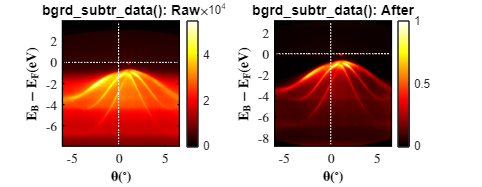

bgrdType    = "AngleInt-clip";
bgrdWin     = [];
bgrdScale   = 0.75;
bgrdSmooth  = 25;
normType    = "max-each";
bgrd_args   = {bgrdType, bgrdWin, bgrdScale, bgrdSmooth, normType}; 
for i = 1:length(arpes_dat)
    if i ==1;   arpes_dat{i} = bgrd_subtr_data(arpes_dat{i}, bgrd_args, 1); 
    else;       arpes_dat{i} = bgrd_subtr_data(arpes_dat{i}, bgrd_args); 
    end
end

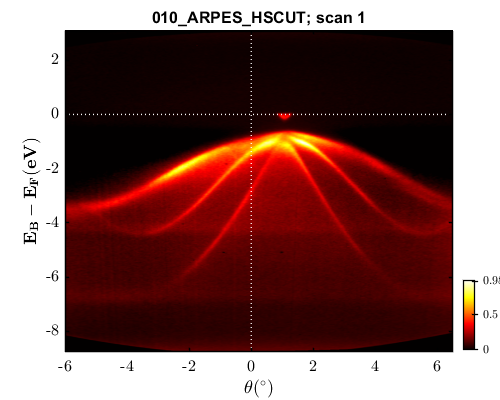

view_arpes_data(arpes_dat{1});

**(E) Wave-vector conversions**

help convert_to_k;

  dataStr = convert_to_k(dataStr, kconv_args, plot_result)
    - #3 - THIRD STEP IN PROCESSING ARPES DATA
    This is a function that will convert the angles thtA into kx and the
    scan parameters into either ky (for tltM) or kz (for hv).  Last updated in
    October 2022, and includes input for new X-ray incidence angle.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   surfNormX = SurfNormX(hv, eB_ref, kx_ref, thtM, thtA_ref) calculates the surface normal angle in the MP.
    -   Kxx = Kxx(HV, Eb, thtM, ThtA, surfNormX) calculates k// in the MP.
    -   Kyy = Kyy(HV, Eb, thtM, TltM, surfNormX) calculates k// in the MP.
    -   Kzz = Kzz(HV, Eb, thtM, ThtA, TltM, v000, surfNormX) calculates kz along the surface normal.
 
    IN:
    -   dataStr:        data structure of the ARPES data.
    -   kconv_args:     {1×5} cell of {eB_ref, kx_ref, thtA_ref, v000, incAlpha}.
                                eB_ref:    	single,

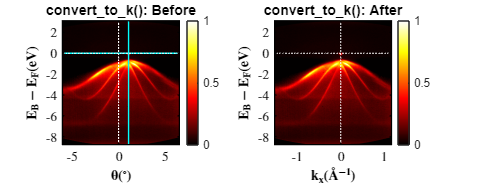

eB_ref      = 0;
kx_ref      = 0;
thtA_ref    = 1.07;
v000        = 12.57;
inc_alpha   = 20;
kconv_args  = {eB_ref, kx_ref, thtA_ref, v000, inc_alpha}; 
for i = 1:length(arpes_dat)
    if i ==1;   arpes_dat{i} = convert_to_k(arpes_dat{i}, kconv_args, 1);
    else;       arpes_dat{i} = convert_to_k(arpes_dat{i}, kconv_args);
    end
    % -- custom shift to centralise kx
    arpes_dat{i}.kx = arpes_dat{i}.kx - 0.0;
end

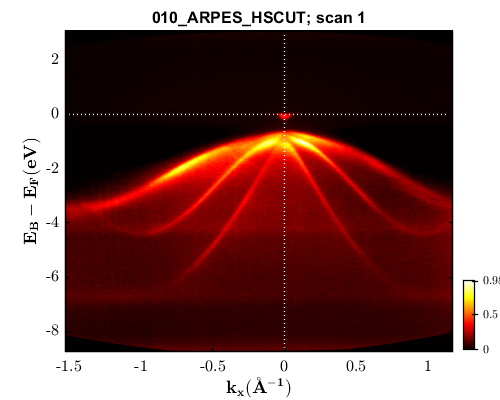

view_arpes_data(arpes_dat{1});

**(F) Cropping the ARPES data**

help data_crop3D;

  dataStr = crop_data(dataStr, xField_lims, yField_lims, zField_lims)
    This function crops the ARPES x-, y- and z-independent variables over
    a given range. The function crops the most recently processed data and
    ensures consistency across both the independent variables and data
    matrix.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
 
    IN:
    -   dataStr:        loaded MATLAB data structure.
  	-   xField_lims:    [1 x 2] row vector of xField ('raw_tht', 'tht', 'kx') crop limits.
  	-   yField_lims:    [1 x 2] row vector of yField ('raw_eb', 'eb') crop limits.
 	-   zField_lims:    [1 x 2] row vector of zField ('hv / tltM', 'kz / ky') crop limits.
 
    OUT:
    -   dataStr:        modified and cropped ARPES data structure.



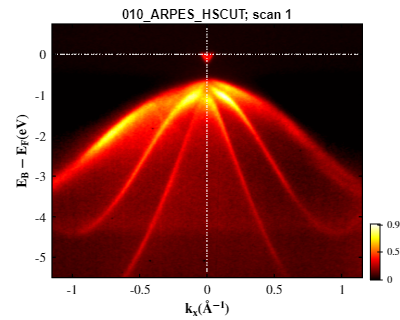

ans = struct with fields:
       FileName: '010_ARPES_HSCUT'
         H5file: '010_ARPES_HSCUT.h5'
      TimeStamp: "05-Oct-2021 16:58:40"
           Type: "Eb(k)"
          index: 1
           meta: [1×1 struct]
       raw_data: [1376×391 double]
        raw_tht: [-6 -5.9679 -5.9359 -5.9038 -5.8718 -5.8397 -5.8077 … ]
         raw_eb: [1376×1 double]
            deb: 0.0450
             hv: 586
            dhv: 0.0750
           tltM: 2.8006
           tltE: NaN
           thtM: 0
           Temp: 81.9000
      eb_shifts: {[1 0.8378]  [1 -0.0121]}
    eb_ref_file: {'010_ARPES_HSCUT_EF'  '010_ARPES_HSCUT_EF'}
             eb: [724×335 double]
            tht: [724×335 double]
           data: [724×335 double]
      surfNormX: 0.2221
             kx: [724×335 double]
             ky: 0.6060
             kz: 12.5701

% -- Extracting the vb and cb
xLims       = [-1.15, 1.15];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-5.5, 0.75];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(arpes_dat) 
    vb_dat{i} = data_crop3D(arpes_dat{i}, xLims, yLims, zLims);
    % - Normalising the intensity
    vb_dat{i}.data = vb_dat{i}.data - min(vb_dat{i}.data(:));
    vb_dat{i}.data = vb_dat{i}.data ./ max(vb_dat{i}.data(:));
    view_arpes_data(vb_dat{i}); vb_dat{i}
end

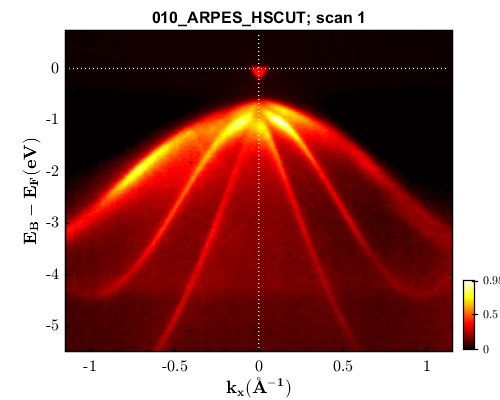

ans = struct with fields:
       FileName: '010_ARPES_HSCUT'
         H5file: '010_ARPES_HSCUT.h5'
      TimeStamp: "05-Oct-2021 16:58:40"
           Type: "Eb(k)"
          index: 1
           meta: [1×1 struct]
       raw_data: [1376×391 double]
        raw_tht: [-6 -5.9679 -5.9359 -5.9038 -5.8718 -5.8397 -5.8077 … ]
         raw_eb: [1376×1 double]
            deb: 0.0450
             hv: 586
            dhv: 0.0750
           tltM: 2.8006
           tltE: NaN
           thtM: 0
           Temp: 81.9000
      eb_shifts: {[1 0.8378]  [1 -0.0121]}
    eb_ref_file: {'010_ARPES_HSCUT_EF'  '010_ARPES_HSCUT_EF'}
             eb: [724×335 double]
            tht: [724×335 double]
           data: [724×335 double]
      surfNormX: 0.2221
             kx: [724×335 double]
             ky: 0.6060
             kz: 12.5701

view_arpes_data(vb_dat{1}); vb_dat{1}

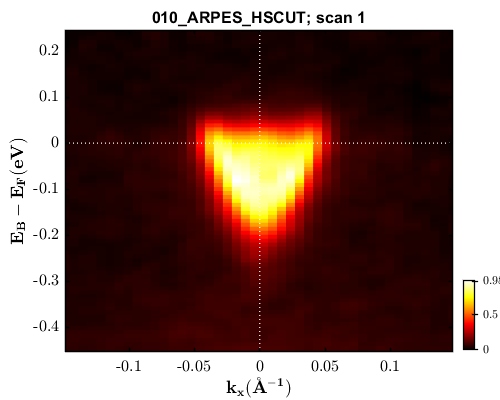

ans = struct with fields:
       FileName: '010_ARPES_HSCUT'
         H5file: '010_ARPES_HSCUT.h5'
      TimeStamp: "05-Oct-2021 16:58:40"
           Type: "Eb(k)"
          index: 1
           meta: [1×1 struct]
       raw_data: [1376×391 double]
        raw_tht: [-6 -5.9679 -5.9359 -5.9038 -5.8718 -5.8397 -5.8077 … ]
         raw_eb: [1376×1 double]
            deb: 0.0450
             hv: 586
            dhv: 0.0750
           tltM: 2.8006
           tltE: NaN
           thtM: 0
           Temp: 81.9000
      eb_shifts: {[1 0.8378]  [1 -0.0121]}
    eb_ref_file: {'010_ARPES_HSCUT_EF'  '010_ARPES_HSCUT_EF'}
             eb: [82×44 double]
            tht: [82×44 double]
           data: [82×44 double]
      surfNormX: 0.2221
             kx: [82×44 double]
             ky: 0.6060
             kz: 12.5701

% -- Cropping around the cb only
xLims       = [-0.15, 0.15];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-0.45, 0.25];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(arpes_dat) 
    cb_dat{i} = data_crop3D(arpes_dat{i}, xLims, yLims, zLims);
    % - Normalising the intensity
    cb_dat{i}.data = cb_dat{i}.data - min(cb_dat{i}.data(:));
    cb_dat{i}.data = cb_dat{i}.data ./ max(cb_dat{i}.data(:));
    view_arpes_data(cb_dat{i}); cb_dat{i}
end

**(G) Binding energy re-alignment to make sure EF is correct**

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


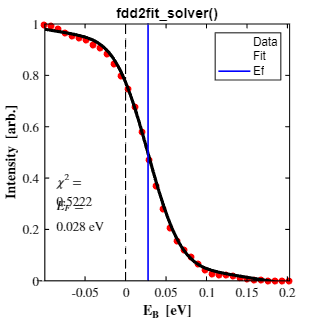

Ef = 0.0278

alignType   = "fit2ef-5%";             % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];                   % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.05;                 % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.15;                 % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];                   % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';               % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(cb_dat)
    cb_dat{i}  = align_energy(cb_dat{i}, align_args, [], 1); 
    vb_dat{i}.eb = vb_dat{i}.eb - cb_dat{i}.eb_shifts{end}(2);
end

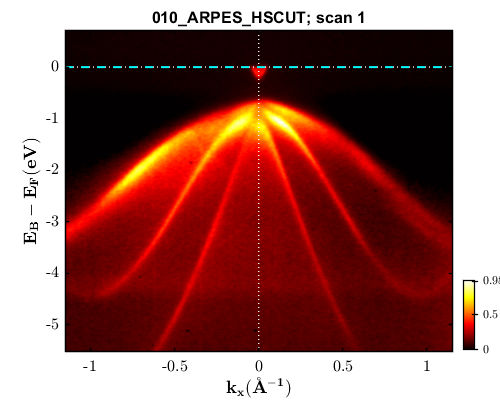

view_arpes_data(vb_dat{1}); line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

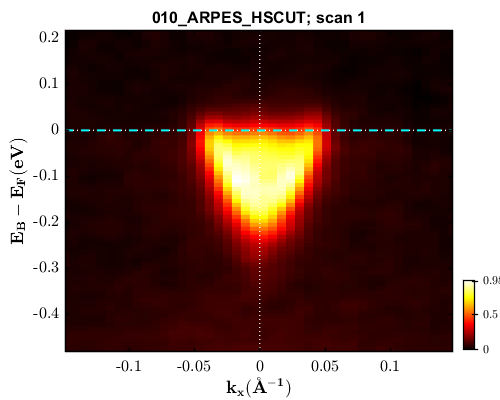

view_arpes_data(cb_dat{1}); line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

# **(2.1) FitVB2LP: Fit the Valence Band to the Leading Peak position**

**(A) Initialising the ARPES data to be fitted**

arpes_fit               = struct();
arpes_fit.FileName      = file_names;
arpes_fit.repeats       = length(vb_dat);
arpes_fit.data          = vb_dat;

**(B) VB Peak Position Determintion**

- Data cut formation


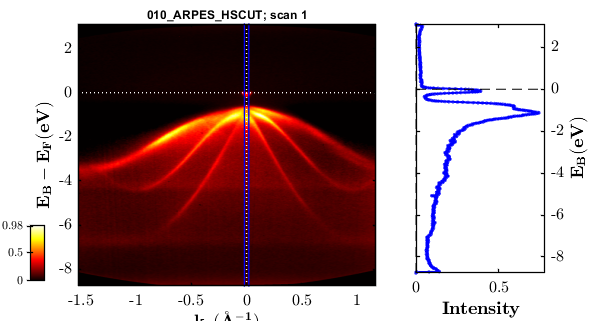

1) x = -0.77 eV, y = 0.60 


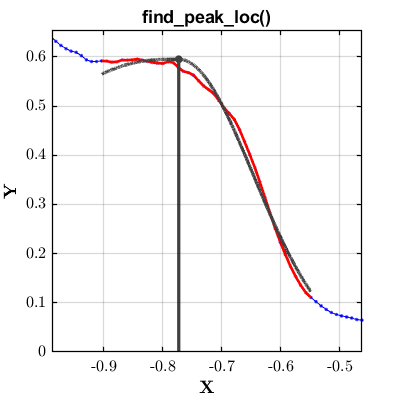

cutType         = "EDC";                    % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = 0.00 + [-0.02, 0.02];     % Integration window of the cut to be made.
isocut_args     = {[], cutType, cutWin};
xWin         = [-0.90, -0.55];
for i = 1:length(arpes_fit.data) 
    arpes_fit.cuts{i} = extract_isoCut(arpes_dat{i}, isocut_args, 1);
    [arpes_fit.VBM(i), ~] = find_peak_loc(arpes_fit.cuts{i}.XCut, arpes_fit.cuts{i}.DCut, xWin, "sGLA", 1);
end

**(C) Finding the best estimate of peak position**

VBM     = arpes_fit.VBM;
% -- Isolating any potential outliers
XX              = 1:length(VBM);
TF              = isoutlier(VBM); TF(1:end) = 0;
XX_adj{1}       = XX(~TF);
XX_adj{2}       = XX(TF);
VBM_adj{1}      = VBM(~TF);
VBM_adj{2}      = VBM(TF);
% -- Redefining arpes_fit.fits and VBM
arpes_fit.cuts  = arpes_fit.cuts(~TF);
VBM             = VBM(~TF);
% -- Final assignments
VBM_mu          = mean(VBM)

VBM_mu = -0.7728

VBM_3sig        = 3*std(VBM)

VBM_3sig = 0

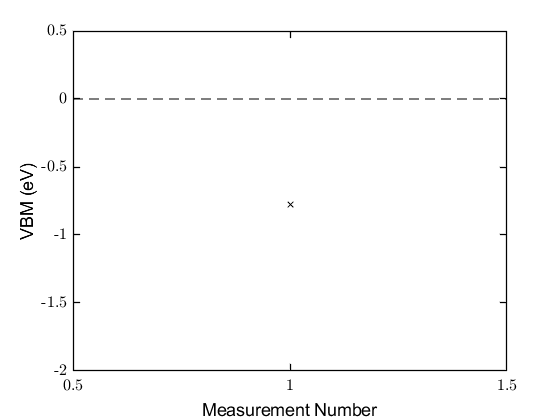

% -- Plotting the result of outlier analysis
figure(); hold on;
plot(XX_adj{1}, VBM_adj{1}, 'kx');
plot(XX_adj{2}, VBM_adj{2}, 'rx');
gca_props();
xlim([0.5, length(arpes_fit.data)+0.5]);
xlabel('Measurement Number');
ylabel('VBM (eV)');

# **(2.2) FitVB2LE: Fit the Valence Band to the Leading Edge position**

**(A) Initialising the ARPES data to be fitted**

arpes_fit               = struct();
arpes_fit.FileName      = file_names;
arpes_fit.repeats       = length(vb_dat);
arpes_fit.data          = vb_dat;

**(B) VB Leading Edge Fitting Method**

- Data cut formation


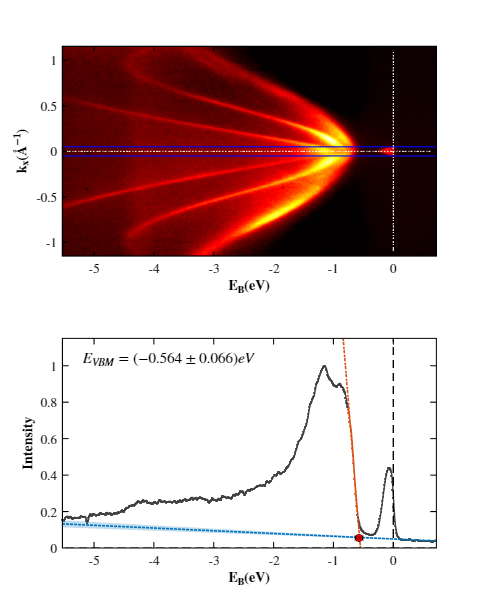

arpes_fit.fits       = {};
bgrnd_type      = "poly1";                  % "poly0" (flat background), "poly1" (linear background), "none" (to the x-axis baseline)
kWin_edc        = 0.00 + [-0.05, 0.05];     % window of the EDC taken around the VBM position
eWin_back	    = [0.15, 1.50];          % window of the background region within the EDC cut
eWin_edge	    = [-0.75, -0.60];           % window of the VBM leading edge region within the EDC cut
dESmooth        = [];                       % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
iparams         = {kWin_edc, eWin_back, eWin_edge, dESmooth}; 
% -- Finding the VBM position from the leading edge fit
for i = 1:length(vb_dat)
    arpes_fit.fits{i} = vb2le_solver(vb_dat{i}.kx, vb_dat{i}.eb, vb_dat{i}.data, bgrnd_type, iparams, 1);
end

arpes_fit.fits{1}

ans = struct with fields:
    vb_fit_args: {[-0.0500 0.0500]  [0.1500 1.5000]  [-0.7500 -0.6000]  []}
           XCut: [724×1 double]
           DCut: [724×1 double]
      XCut_back: [67×1 double]
      DCut_back: [67×1 double]
      XCut_edge: [18×1 double]
      DCut_edge: [18×1 double]
       fit_back: [1×1 cfit]
       fit_edge: [1×1 cfit]
             XX: [1000×1 double]
        DD_back: [1000×1 double]
        DD_edge: [1000×1 double]
            VBM: -0.5640
           dVBM: 0.0660
        VBM_int: 0.0580
       dVBM_int: 0.0040

**(C) Finding the best estimate of peak position**

VBM     = zeros(1,length(arpes_dat)); 
for i = 1:length(arpes_fit.fits)
    VBM(i)      = arpes_fit.fits{i}.VBM;
end
% -- Isolating any potential outliers
XX              = 1:length(VBM);
TF              = isoutlier(VBM); TF(1:end) = 0;
XX_adj{1}       = XX(~TF);
XX_adj{2}       = XX(TF);
VBM_adj{1}      = VBM(~TF);
VBM_adj{2}      = VBM(TF);
% -- Redefining arpes_fit.fits and VBM
arpes_fit.cuts  = arpes_fit.fits(~TF);
VBM             = VBM(~TF);
% -- Final assignments
VBM_mu          = mean(VBM)

VBM_mu = -0.5640

VBM_3sig        = 3*std(VBM)

VBM_3sig = 0

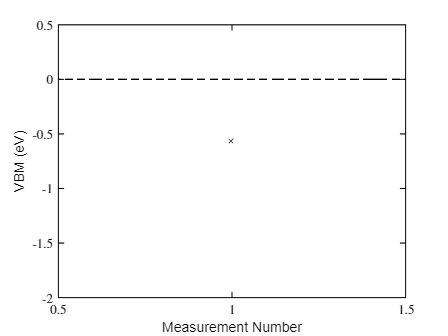

% -- Plotting the result of outlier analysis
figure(); hold on;
plot(XX_adj{1}, VBM_adj{1}, 'kx');
plot(XX_adj{2}, VBM_adj{2}, 'rx');
gca_props();
xlim([0.5, length(arpes_fit.data)+0.5]);
xlabel('Measurement Number');
ylabel('VBM (eV)');

# **(2.3) SX-ARPES Fitting Algorithm - Fitting to CB states**

The PESTools functions offers a method to fit N parabola to SX-ARPES data, which is particularly useful when fitting to quantum well states. 

The general objective of fitting the ARPES data is to define a series of N parabola, that are each displaced in energy, relative to the Fermi-level. A reasonable first guess must be made, and then an optimisation procedure is used to hone in to the best fit solution. Here, the general procedures are listed below;

- Define the **shape** and **properties** of the *N* parabolic states to be fitted

- Define the properties of the **Fermi-Dirac Distribution (FDD)** and **linear** **background**

- Preview the initial conditions of the ARPES fit model vs data

- If you are happy with the initial guess, use 'arpes2nbola_solver()' to run the optimisation algorithm

**(A) Initialising the ARPES data to be fitted**

arpes_fit               = struct();
arpes_fit.FileName      = file_names;
arpes_fit.repeats       = length(cb_dat);
arpes_fit.data          = cb_dat;

**(B) Initialising the ARPES data to be fitted**

iparams = {};
% DEFINING THE TYPES OF CURVES TO BE USED
cTYPE   = ["G2DA"; "G2DA"];       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
% 1 - DEFINING THE INITIAL CONDITIONS OF THE ARPES COMPONENTS
INT     = [0.546; 0.40];          % scalar of the peak intensity of 2D PE curve.
XLOC    = [0.0; 0.0];             % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = [-0.16; -0.05];         % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = [0.02; 0.02];         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = [0.12; 0.12];         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = [0.03; 0.03];         % scalar of the effective mass, which governs the curvature of the parabola.
iparams{1} = [INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR]; iparams{1}

ans =     0.5460         0   -0.1600    0.0200    0.1200    0.0300
    0.4000         0   -0.0500    0.0200    0.1200    0.0300


% 2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
iparams{2} = iparams{1}; 
iparams{2}(:,1) = iparams{1}(:,1) - 5.00;
iparams{2}(:,2) = iparams{1}(:,2) - 0.005; 
iparams{2}(:,3) = iparams{1}(:,3) - 0.10; 
iparams{2}(:,4) = iparams{1}(:,4) - 0.05; 
iparams{2}(:,5) = iparams{1}(:,5) - 0.10; 
iparams{2}(:,6) = iparams{1}(:,6) - 0.02;
iparams{2}

ans =    -4.4540   -0.0050   -0.2600   -0.0300    0.0200    0.0100
   -4.6000   -0.0050   -0.1500   -0.0300    0.0200    0.0100


% -- Upper bounds
iparams{3}      = iparams{1}; 
iparams{3}(:,1) = iparams{1}(:,1) + 5.00;
iparams{3}(:,2) = iparams{1}(:,2) + 0.005; 
iparams{3}(:,3) = iparams{1}(:,3) + 0.10; 
iparams{3}(:,4) = iparams{1}(:,4) + 0.05; 
iparams{3}(:,5) = iparams{1}(:,5) + 0.10; 
iparams{3}(:,6) = iparams{1}(:,6) + 0.02;
iparams{3}

ans =     5.5460    0.0050   -0.0600    0.0700    0.2200    0.0500
    5.4000    0.0050    0.0500    0.0700    0.2200    0.0500



% 2.0 - DEFINING THE BACKGROUND PARAMETERS
FDEF    =  0.00;        % scalar of the FDD Fermi-Level position.
FDT     =  12.0;        % scalar of the FDD temperature.
FDW     =  0.10;        % scalar of the FDD Gaussian width after convolution.
BGR     =  0.00;        % scalar of the gradient of the linear background.
BIN     =  0.05;         % scalar of the y-intercept of the linear background.
BCO     =  0.10;        % scalar of the constant background y-offset value.
ibgrnd{1} = [FDEF, FDT, FDW, BGR, BIN, BCO]; 
ibgrnd{1}

ans =          0   12.0000    0.1000         0    0.0500    0.1000


% 2.1 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
ibgrnd{2}       = ibgrnd{1}; 
ibgrnd{2}(1)    = ibgrnd{1}(1) - 0.00;
ibgrnd{2}(2)    = ibgrnd{1}(2) - 0.00;
ibgrnd{2}(3)    = ibgrnd{1}(3) - 0.10;
ibgrnd{2}(4)    = ibgrnd{1}(4) - 0.10;
ibgrnd{2}(5)    = ibgrnd{1}(5) - 0.10;
ibgrnd{2}(6)    = ibgrnd{1}(6) - 0.10;
ibgrnd{2}

ans =          0   12.0000         0   -0.1000   -0.0500         0


% -- Upper bounds
ibgrnd{3}       = ibgrnd{1}; 
ibgrnd{3}(1)    = ibgrnd{1}(1) + 0.00;
ibgrnd{3}(2)    = ibgrnd{1}(2) + 0.00;
ibgrnd{3}(3)    = ibgrnd{1}(3) + 0.10;
ibgrnd{3}(4)    = ibgrnd{1}(4) + 0.10;
ibgrnd{3}(5)    = ibgrnd{1}(5) + 0.10;
ibgrnd{3}(6)    = ibgrnd{1}(6) + 0.10;
ibgrnd{3}

ans =          0   12.0000    0.2000    0.1000    0.1500    0.2000


- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation


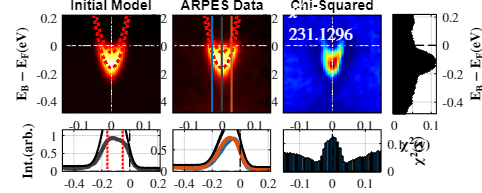


% 3 - Preview the initial conditions of the model vs data fit
arpes2nbola_view_init(arpes_fit.data{1}, cTYPE, iparams, ibgrnd);

**(C) Execute ARPES fitting algorithm**


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation


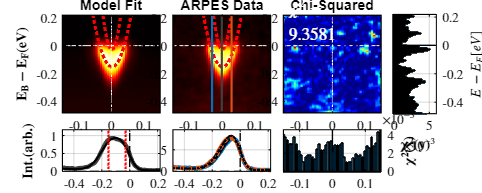

ans = struct with fields:
    solve_type: "fmincon"
       iparams: {[2×6 double]  [2×6 double]  [2×6 double]}
        ibgrnd: {1×3 cell}
            kx: [-0.1492 -0.1423 -0.1354 -0.1285 -0.1216 -0.1147 -0.1077 … ]
            eb: [82×1 double]
       kx_lims: [-0.1492 0.1481]
       eb_lims: [-0.4818 0.2180]
             D: [82×44 double]
             M: [82×44 double]
             R: [82×44 double]
            Rx: [-0.0101 -0.0080 -0.0074 -0.0073 -0.0061 -0.0045 -0.0050 … ]
            Ry: [82×1 double]
       CHISQ2D: [82×44 double]
        CHISQx: [0.0042 0.0039 0.0035 0.0031 0.0031 0.0039 0.0031 0.0023 … ]
        CHISQy: [82×1 double]
         CHISQ: 9.3581
        MINFUN: 9.3581
           DoF: 16
        params: [18×1 double]
             n: 2
         cTYPE: [2×1 string]
           INT: [2×1 double]
          XLOC: [2×1 double]
          YLOC: [2×1 double]
         XFWHM: [2×1 double]
         YFWHM: [2×1 double]
         MSTAR: [2×1 double]
          FDEF: 0
           FDT: 1

solve_type  = "fmincon";
tic
for i = 1:length(arpes_fit.data)
    arpes_fit.fit{i} = arpes2nbola_solver(arpes_fit.data{i}, cTYPE, iparams, ibgrnd, solve_type);
    arpes2nbola_view_fit(arpes_fit.fit{i}); arpes_fit.fit{i}
end

toc

Elapsed time is 46.002772 seconds.


**(D) Printing out the fit information**

for i = 1:length(arpes_fit.data)
    for j = 1:length(arpes_fit.fit{i}.INT)
        info = "";
        info = info + sprintf("File: \t\t %i \n", i);
        info = info + sprintf("N: \t\t %i \n", j);
        info = info + sprintf("INT: \t\t %.3f \n", arpes_fit.fit{i}.INT(j));
        info = info + sprintf("XLOC: \t\t %.3f \n", arpes_fit.fit{i}.XLOC(j));
        info = info + sprintf("YLOC: \t\t %.3f \n", arpes_fit.fit{i}.YLOC(j));
        info = info + sprintf("XFWHM: \t\t %.3f \n", arpes_fit.fit{i}.XFWHM(j));
        info = info + sprintf("YFWHM: \t\t %.3f \n", arpes_fit.fit{i}.YFWHM(j));
        info = info + sprintf("MSTAR: \t\t %.3f \n\n", arpes_fit.fit{i}.MSTAR(j));
        fprintf(info);
    end
end

File: 		 1 
N: 		 1 
INT: 		 0.407 
XLOC: 		 0.002 
YLOC: 		 -0.153 
XFWHM: 		 0.010 
YFWHM: 		 0.172 
MSTAR: 		 0.034 

File: 		 1 
N: 		 2 
INT: 		 0.143 
XLOC: 		 0.001 
YLOC: 		 -0.029 
XFWHM: 		 0.070 
YFWHM: 		 0.220 
MSTAR: 		 0.011 

